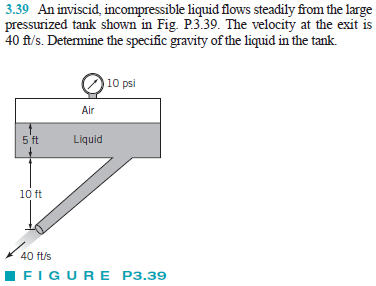

# given

u = symunit;
rho_water = 1.94*u.slug/u.ft^3;
g = 32.2*u.ft/u.s^2;

# state 1

p1 = 10*u.psi;
V1 = 0;
z1 = 15*u.ft;

# state 2

p2 = 0;
V2 = 40*u.ft/u.s;
z2 = 0;

# Bernoulli's Equation

SG = sym('SG');
rho(SG) = SG*rho_water;
SG = simplify(solve(p1+rho*V1^2/2+rho*g*z1 == p2+rho*V2^2/2+rho*g*z2));